clr(); 

# Numerical settings

L = 100;  % set softrobot (intrinsic) length
N = 70;   % number of discrete points on curve
M = 5;    % number of modes

# Creating an (strain) orthonormal basis

% generate nodal space
X = linspace(0,L,N)';

% loop over functional space
Y = zeros(N,M);
for ii = 1:M
   %Y(:,ii) = legendre(X,ii-1);     % legendre
   Y(:,ii) = chebyshev(X/L,ii-1);   % chebyshev
   %Y(:,ii) = X.^(ii-1);            % affine curvature (same as chebyshev, after gram–schmidt)
end

% ensure its orthonormal (gram–schmidt)
Y = gsogpoly(Y,X);

# Orthonormality check

% checking orthonormality
set = unique(nchoosek(sort([1:M,1:M]),2),'rows');
P = zeros(M,M);
for ii = 1:size(set,1)
    poly1 = set(ii,1);
    poly2 = set(ii,2);
    P(poly1,poly2) = trapz(X,Y(:,poly1).*Y(:,poly2));
end

% should give the identity of size M.
P = 0.5*(P.' + P)

P =     1.0000    0.0000   -0.0000    0.0000   -0.0000
    0.0000    1.0000    0.0000   -0.0000   -0.0000
   -0.0000    0.0000    1.0000   -0.0000    0.0000
    0.0000   -0.0000   -0.0000    1.0000         0
   -0.0000   -0.0000    0.0000         0    1.0000


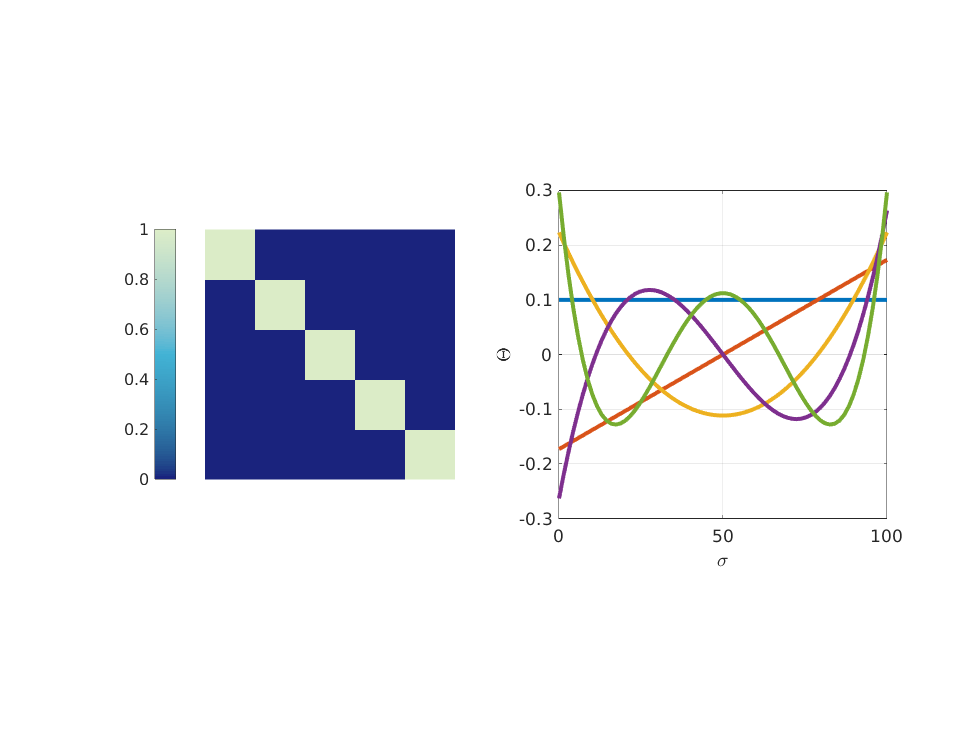


% plotting
figure;
subplot(1,2,1);
imshow(P); 
axis square; axis off; 
colorbar('Location','westoutside');
caxis([0 1]);
colormap(bluesea); 

subplot(1,2,2);
plot(X,Y,'LineWidth',3); 
grid on; axis square;
xlabel('\sigma');
ylabel('\Theta');

# Creating the Shape class

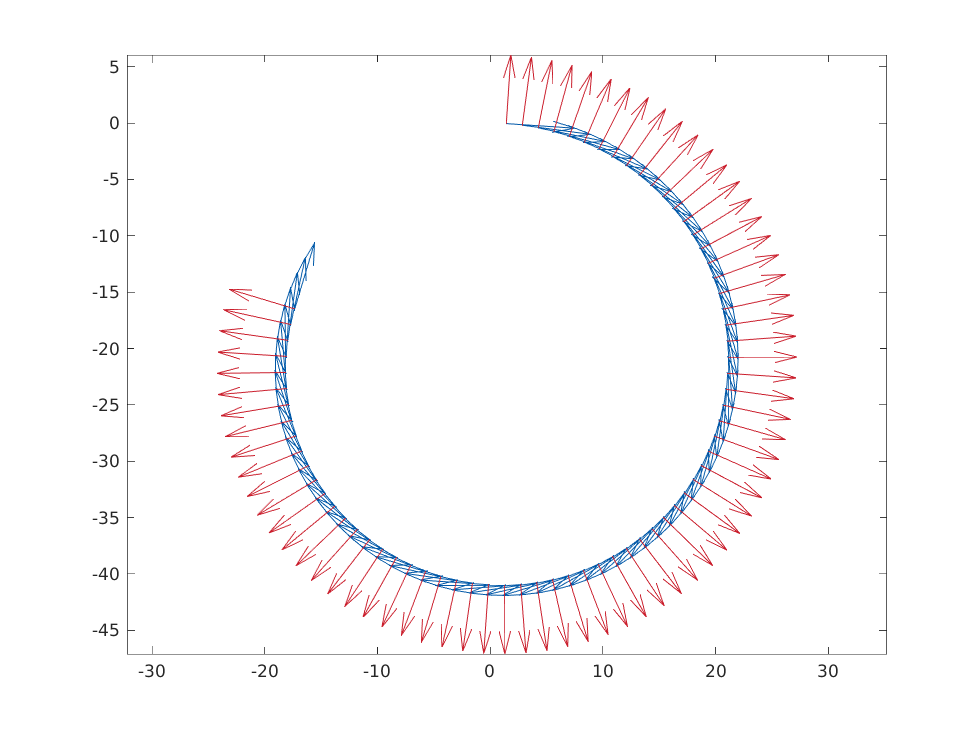

Modes = [0,M,0,0,0,0];   % pure curvature
%Modes = [0,M,0,M,0,0];  % curvature-elongation

shp = Shapes(Y,Modes,'L0',L);

q = zeros(shp.NDim,1);
q(1) = 0.5; q(2) = 0.02;

%% generate Cosserat string
g = shp.string(q);

figure;
plotSE2(g);
axis equal; box on;

# Setting the Material options

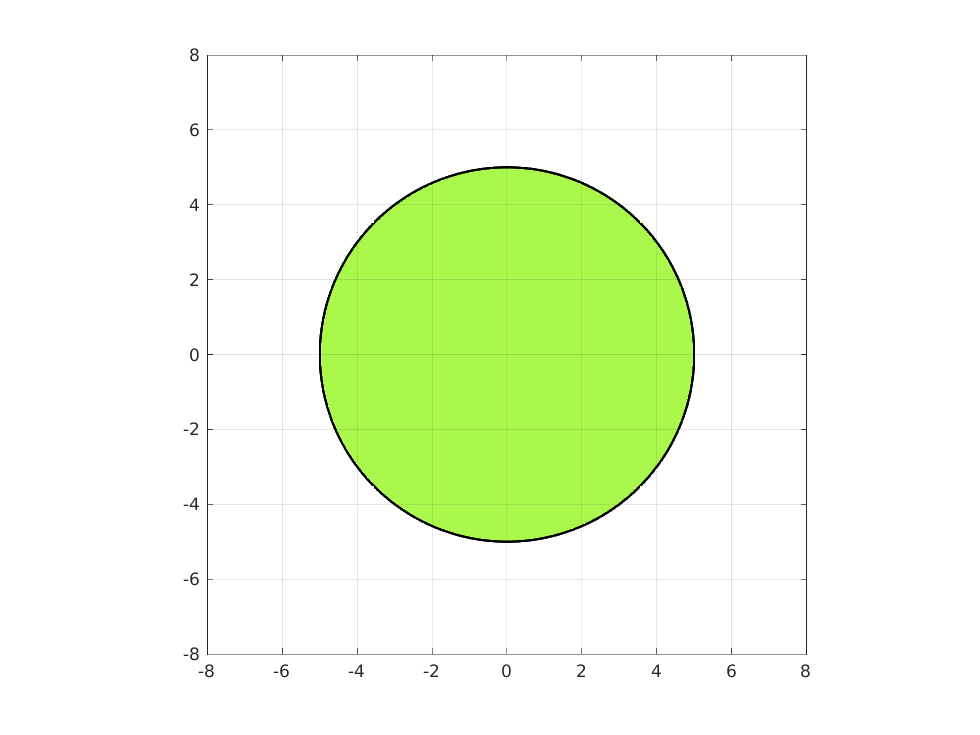

shp.E    = 12.00;    % Young's modulus in Mpa
shp.Nu   = 0.49;     % Poisson ratio
shp.Rho  = 1000e-12; % Density in kg/mm^3
shp.Zeta = 0.1;      % Damping coefficient

figure;
shp.Sdf.showcontour();  % cross-section
view(0,90); axis equal; axis([-8 8 -8 8]);


shp = shp.rebuild(); % ensure all material tensors are computed correctly

# Creating the Model class

mdl = Model(shp,'Tsim',2);

mdl.q0(1) = -2.0;

% simulate with zero intial conditions
mdl = mdl.simulate();

----------------------------------
* Computing SR dynamics... (1 %  )


 (1 %  )


 (2 %  )


 (3 %  )


 (4 %  )


 (5 %  )


 (6 %  )


 (6 %  )


 (7 %  )


 (8 %  )


 (9 %  )


 (10 % )


 (11 % )


 (11 % )


 (12 % )


 (13 % )


 (14 % )


 (15 % )


 (16 % )


 (16 % )


 (17 % )


 (18 % )


 (19 % )


 (20 % )


 (20 % )


 (21 % )


 (22 % )


 (23 % )


 (24 % )


 (25 % )


 (25 % )


 (26 % )


 (27 % )


 (28 % )


 (29 % )


 (30 % )


 (30 % )


 (31 % )


 (32 % )


 (33 % )


 (34 % )


 (35 % )


 (35 % )


 (36 % )


 (37 % )


 (38 % )


 (39 % )


 (39 % )


 (40 % )


 (41 % )


 (42 % )


 (43 % )


 (44 % )


 (44 % )


 (45 % )


 (46 % )


 (47 % )


 (48 % )


 (49 % )


 (49 % )


 (50 % )


 (51 % )


 (52 % )


 (53 % )


 (54 % )


 (54 % )


 (55 % )


 (56 % )


 (57 % )


 (58 % )


 (59 % )


 (59 % )


 (60 % )


 (61 % )


 (62 % )


 (63 % )


 (63 % )


 (64 % )


 (65 % )


 (66 % )


 (67 % )


 (68 % )


 (68 % )


 (69 % )


 (70 % )


 (71 % )


 (72 % )


 (73 % )


 (73 % )


 (74 % )


 (75 % )


 (76 % )


 (77 % )


 (78 % )


 (78 % )


 (79 % )


 (80 % )


 (81 % )


 (82 % )


 (82 % )


 (83 % )


 (84 % )


 (85 % )


 (86 % )


 (87 % )


 (87 % )


 (88 % )


 (89 % )


 (90 % )


 (91 % )


 (92 % )


 (92 % )


 (93 % )


 (94 % )


 (95 % )


 (96 % )


 (97 % )


 (97 % )


 (100 %) Done! 
----------------------------------
* Number of elem.  = 70
* Computation time = 5.36 s
* Computation freq = 60 Hz
* Real-time ratio  = 0.3731
----------------------------------


# Animation

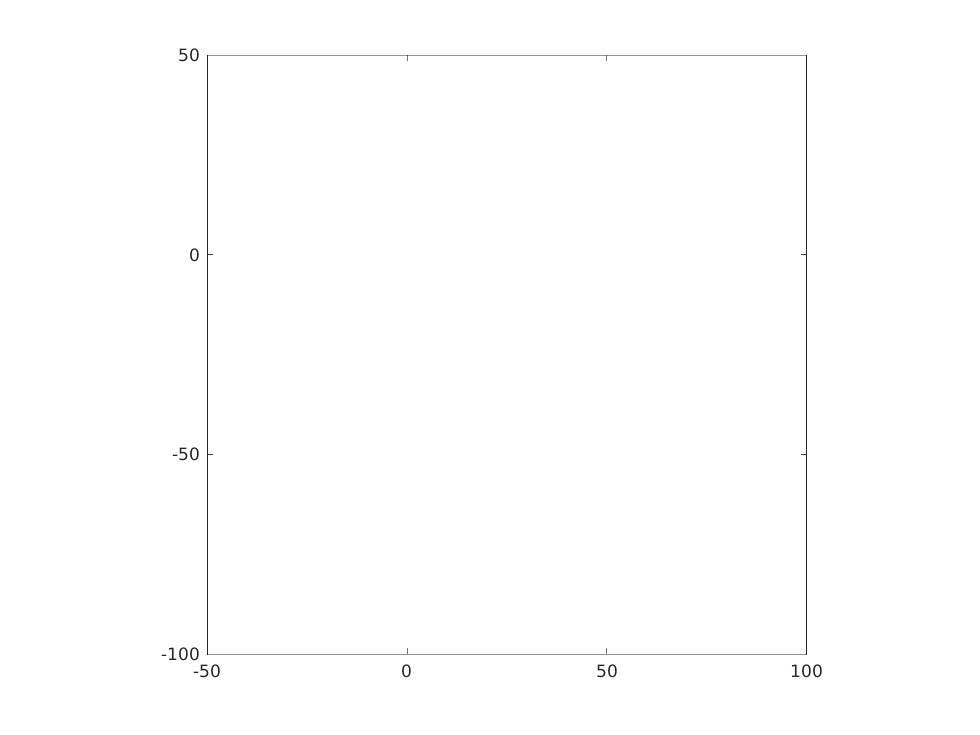

figure; clf;
t = mdl.Log.t;
Q = mdl.Log.q; % get state at t_i

for ii = 1:fps(t,40):numel(mdl.Log.t)
    
    % solve Forward-Kin
    p = shp.FK(Q(ii,:).');
    
    % plot   
    plot(p(:,1),p(:,3),'LineWidth',2,...
        'Color',col(1)); 
    
    %hold on;
    axis equal
    axis([-0.5*L L -L 0.5*L]); 
    drawnow;
    
end    